# LAB 5: SEP of an Airbus A340-300

Authors: Niklas Gierse (nikgi434), Leonhard Mühlstrasser (leomu719)

## Lab Results

### Task 2 & 3: SEP Calculation

%%%% Data Setup
clear livescript

% acdata = load('data/actable.mat')
mtow = 271000; % [kg]
staticthrust = 151000 * 4; % [N], from acdata, 4 engines
g = 9.80665; % [m/s^2]
Sref = 363.1; % [m^2]
weight = 0.8*mtow*g;

% Boundaries
qmax = 12500; % TODO
mne = 0.93;
clmax = 2.61; % TODO

altstepsize = 100;
alts = 0:altstepsize:15000;
speeds = 0:0.05:1;

servicelimit_sep = 500*(0.3048/60);


% Calculate SEP values
for iAlts=1:numel(alts)
    for iSpeeds=1:numel(speeds)
        % Calculate SEP value
        thr = calculateThrust(staticthrust, alts(iAlts), speeds(iSpeeds));

        [ignore1, ignore2, rho, a] = ISAfunction(alts(iAlts));

        vel = speeds(iSpeeds) * a;

        [pDrag, iDrag] = dragFunction(alts(iAlts), vel);

        drag = pDrag + iDrag;

        sep(iAlts,iSpeeds) = (vel/weight) * (thr - drag);

        % Remove it if outside boundaries

        % Mne
        if speeds(iSpeeds) > mne
            sep(iAlts,iSpeeds) = nan;
        end

        % Max dynamic pressure
        if 0.5*rho*vel*vel > qmax
            sep(iAlts,iSpeeds) = nan;
        end
        
        % Airspace speed limitation
        if alts(iAlts) <= 3000 && vel > (250*1.852/3.6)
            sep(iAlts,iSpeeds) = nan;
        end

        % CLmax
        clNeeded = weight / (Sref*0.5*rho*vel*vel);
        if clNeeded > clmax
            sep(iAlts,iSpeeds) = nan;
        end
    end
end


% Plot
hold off
hold on
% SEP
contour(speeds, alts, sep, [0:5:30, 500*(0.3048/60)])
xlabel('Mach [-]')
ylabel('Altitude [m]')
title('Flight Envelope: A340-300')
legend('SEP [m/s]')

% Envelope Boundaries
% plot([0.3, 1], [3000, 3000], 'k')


### Task 4: Time-optimal climb path

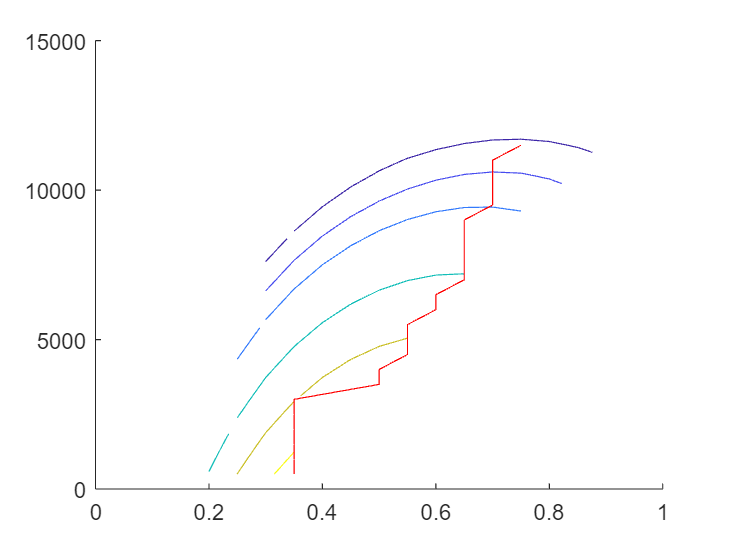

for i=1:numel(alts)
    bestSEP = max(sep(i,:));
    if bestSEP < 0 || isnan(bestSEP)
        bestSpd(i) = nan;
    else
        bestSpd(i) = speeds(find(sep(i,:) == bestSEP));
    end
end

plot(bestSpd, alts, 'r');

### Task 5: Total time to Service Ceiling (500ft/min)

time = 0;

% Add up time taken for each step with optimum SEP
for i=1:numel(alts)
    opt_sep = max(sep(i,:));
    if opt_sep >= servicelimit_sep
        time = time + (altstepsize/opt_sep);
    end
end

% Time to service ceiling
minutes_500fpm = time/60

minutes_500fpm = 18.3700

### Task 6: Service Ceiling 100ft/min

servicelimit_sep = 100*(0.3048/60);

time = 0;

% Add up time taken for each step with optimum SEP
for i=1:numel(alts)
    opt_sep = max(sep(i,:));
    if opt_sep >= servicelimit_sep
        time = time + (altstepsize/opt_sep);
    end
end

% Time to service ceiling
minutes_100fpm = time/60

minutes_100fpm = 28.2258